## 1.相关性矩阵

这里是计算了皮尔森相关系数，两两通道之间的同一个trail进行计算；

1）如果要多session混合，需要考虑到session内部的排序差异；

2）要考虑先平均trail还是先进行相关系数计算

% 计算相关性矩阵
tic;
session = 2;
cor = [];
% for coil1 = 1:96
%     fieldName =['session',num2str(session)];
%     electrode1 = squeeze(timeseries.(fieldName)(:,coil1,1:1640));
%     for coil2 = 1:96
%          electrode2 = squeeze(timeseries.(fieldName)(:,coil2,1:1640));
%          for i = 1:length(timeseries.(fieldName)(:,1,1))
%             [r,p] = corr(electrode1(i,:)',electrode2(i,:)');
%             cor(i,1,coil1,coil2) = r;
%             cor(i,2,coil1,coil2) = p;
%          end
%     end
% end
ori = 5;
for coil1 = 1:96
    electrode1 = squeeze(all_orient_data(:,:,coil1,ori));
    for coil2 = 1:96
        electrode2 = squeeze(all_orient_data(:,:,coil2,ori));
        for i = 1:length(all_orient_data(:,1,coil2,ori)) 
            [r,p] = corr(electrode1(i,:)',electrode2(i,:)');
            cor(i,1,coil1,coil2) = r;
            cor(i,2,coil1,coil2) = p;
        end
    end
end


toc;

%频谱的相关性
timeLimits = seconds([0 2.08]); % 秒
frequencyLimits = [0 250];
sampleRate = 500; % Hz
startTime = 0; % 秒f
all_fft_data = [];
for ori = 1:9
    for coil = 1:96
        for trail = 1:270
            ROI = squeeze(all_orient_data(trail,420:1440,coil,ori))';%频谱分析要做成列向量
            timeValues = startTime + (0:length(ROI)-1).'/sampleRate;
            ROI = timetable(seconds(timeValues(:)),ROI,'VariableNames',{'Data'});
            ROI = ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
            [P_ROI, F_ROI] = pspectrum(ROI, ...
                'FrequencyLimits',frequencyLimits);            
            all_fft_data(trail,:,coil,ori) = P_ROI(1:1000)';
        end
    end
end
ori = 5;
for coil1 = 1:96
    electrode1 = squeeze(all_fft_data(:,:,coil1,ori));
    for coil2 = 1:96
        electrode2 = squeeze(all_fft_data(:,:,coil2,ori));
        for i = 1:length(all_fft_data(:,1,coil2,ori)) 
            [r,p] = corr(electrode1(i,:)',electrode2(i,:)');
            cor(i,1,coil1,coil2) = r;
            cor(i,2,coil1,coil2) = p;
        end
    end
end


%特征值的相关性
specialfft = [];
for ori = 1:9
    specialfft(:,ori,:) = all_fft_data(:,411,:,ori);
end

cor = [];
for coil1 = 1:96
    electrode1 = squeeze(specialfft(:,:,coil1));
    for coil2 = 1:96
        electrode2 = squeeze(specialfft(:,:,coil2));
        for i = 1:length(specialfft(:,1,coil2)) 
            [r,p] = corr(electrode1(i,:)',electrode2(i,:)');
            cor(i,1,coil1,coil2) = r;
            cor(i,2,coil1,coil2) = p;
        end
    end
end

% 相关性热图
imagesc(squeeze(mean(cor(:,1,:,:),1)))
% p-value
figure(2)
imagesc(squeeze(mean(cor(:,2,:,:),1)))

## **2.聚类**

**采用的是层级聚类方式**

%获得聚类矩阵
%load('D:\Desktop\Ensemble coding\data\cordata.mat')
for x = 1:96
    for y = 1:96
        clusterdata(x,y)=squeeze(mean(cor(:,1,x,y),1));
    end
end
z = linkage(clusterdata,"average");

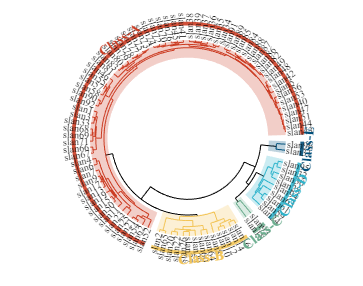

%Stree工具绘制树形图环图
N=5;
ST = STree(z, 'MaxClust', N);

% 改变方向 -- change the orientation
ST.Orientation = 'left';

ST.ClustGap = 'on';        % 每个类之间加入间隙   -- insert gap between each clust
ST.BranchColor = 'on';     % 为不同类树枝添加颜色 -- set the branch's color of each clust
ST.BranchHighlight = 'on'; % 增添树枝高亮         -- add highlight for each clust's branches
ST.Label = 'on';           % 关闭样本标签         -- close sample label
ST.Layout = 'bezier';      % 改变树枝类型         -- change the layout
ST.ClassHighlight = 'on';  % 分类高亮            -- add class highlight
ST.ClassLabel = 'on';      % 分类文本信息         -- add class-label

ST.TLim = [0,2*pi];
close all
% layoutSet = {'rectangular', 'rounded', 'slanted', 'ellipse', 'bezier'};
layoutSet = {'rectangular'};

% 调整各个元素半径 -- adjust the radius of each elementa
% 样本文本 类弧形内侧 类弧形外侧 类文本
% Sample text, inner side of class arc, outer side of class arc, class text
ST.RTick = [1+1/40, 1.4, 1.5, 1.6];
ST.XLim = [2.5,4];
for i = 1:length(layoutSet)
    tempFig = figure('Units', 'normalized', 'Position', [.05,.1,.5,.7], 'Color', 'w'); 
    ST.ax = gca;
    ST.Layout = layoutSet{i};
    ST.draw()

    set(gca,'XColor','none','YColor','none')
    % exportgraphics(tempFig, ['.\gallery\demo7_right_full_fan_XLim_0_3_',layoutSet{i},'.png'])
end

%聚类质量评估
k = 5;
idx = spectralcluster(clusterdata, k); 
[B, S] = evalclusters(clusterdata, idx);
figure;
plot(B);
title('聚类有效性');

## **3.位置相关性**

绘制出通道的正确位置

labels = cell(10, 10);

% 填充单元数组
for i = 1:10
    for j = 1:10
        % 构造标签，例如 'A1', 'A2', ..., 'A10', 'B1', ...
        labels{i, j} = num2str(chan(i,j));
    end
end

% 定义网格大小
N = 10;

% 创建一个10x10的网格
[X, Y] = meshgrid(1:N, 1:N);

% 假设我们有一个10x10的矩阵，每个元素是预先确定的值
% 这里我们使用随机数作为示例
Values = rand(N);

% 绘制网格图
figure;
imagesc(X, Y, Values);

% 添加颜色条
colorbar;

% 设置坐标轴标签
xlabel('X Axis');
ylabel('Y Axis');
title('10x10 Grid with Values');

% 为了在每个格子上显示值，我们可以使用text函数
for i = 1:N
    for j = 1:N
        text(X(j, i), Y(j, i), num2str(Values(i, j), '%0.2f'), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle');
    end
end

% 调整坐标轴使其成为正方形
axis equal;
axis tight;